# Jacobi Test

## Testing di Robustezza

### Testing sul numero di input

A=gallery('poisson',10);
xc=jacobi(A);

Error using jacobi (line 5)
Inserire come input almeno A e b.

### Testing sulla matrice

Testo se è una matrice

A=rand(10,10,10);
b=[1 2 3]';
xc=jacobi(A,b);

Error using jacobi (line 9)
Il primo input deve essere una matrice.

Testo se è sparsa o vuota

A=rand(100,100);
x=ones(100,1);
b=A*x;
xc=jacobi(A,b);

Error using jacobi (line 11)
La matrice deve essere sparsa e non vuota.

A=[];
A=sparse(A);
b=[1 2 3]';
xc=jacobi(A,b);

Error using jacobi (line 11)
La matrice deve essere sparsa e non vuota.

Testo se non è quadrata

A=sparse(rand(100,200));
x=ones(200,1);
b=A*x;
xc=jacobi(A,b);

Error using jacobi (line 13)
La matrice deve essere quadrata.

Testo se è di grandi dimensioni

A=gallery('poisson',5);
x=ones(25,1);
b=A*x;
xc=jacobi(A,b);

Error using jacobi (line 15)
La matrice deve essere di grandi dimensioni(almeno 100x100)

Testo se contiene valori corretti

A=gallery('poisson',10);
A(15,15)=NaN;
x=ones(100,1);
b=A*x;
xc=jacobi(A,b);

Error using jacobi (line 17)
Gli elementi della matrice devono essere numeri reali double finiti.

A=gallery('poisson',10);
A(25,35)=Inf;
x=ones(100,1);
b=A*x;
xc=jacobi(A,b);

Error using jacobi (line 17)
Gli elementi della matrice devono essere numeri reali double finiti.

Controllo se la diagonale ha elementi nulli

A=gallery('poisson',10);
A(25,:)=0;
x=ones(100,1);
b=A*x;
xc=jacobi(A,b);

Error using jacobi (line 22)
Sono presenti elementi nulli all'interno della diagonale principale.

### Testing sul vettore

Testo se è un vettore colonna

A=gallery('poisson',10);
b=10;
xc=jacobi(A,b);

Error using jacobi (line 28)
Errore, b deve essere un vettore colonna.

A=gallery('poisson',10);
x=ones(100,1);
b=(A*x)';
xc=jacobi(A,b);

Error using jacobi (line 28)
Errore, b deve essere un vettore colonna.

Testo se ha le stesse dimensioni della matrice

A=gallery('poisson',10);
b=[1:200]';
xc=jacobi(A,b);

Error using jacobi (line 30)
Il vettore b e la matrice A hanno dimensioni diverse.

Testo se contiene valori corretti

A=gallery('poisson',10);
b=[1:100]';
b(10)=NaN;
xc=jacobi(A,b);

Error using jacobi (line 32)
Errore, b deve contenere reali finiti double.

A=gallery('poisson',10);
b=[1:100]';
b(35)=Inf;
xc=jacobi(A,b);

Error using jacobi (line 32)
Errore, b deve contenere reali finiti double.

### Testing su TOL

Testo se è uno scalare

A=gallery('poisson',10);
x=ones(100,1);
TOL=[1:10];
b=A*x;
xc=jacobi(A,b,TOL);

Error using jacobi (line 40)
Errore, TOL deve essere uno scalare

Testo se ha valore accettabile

A=gallery('poisson',10);
x=ones(100,1);
TOL=Inf;
b=A*x;
xc=jacobi(A,b,TOL);

Error using jacobi (line 42)
Errore, TOL deve essere settato come un numero reale.

A=gallery('poisson',10);
x=ones(100,1);
TOL=NaN;
b=A*x;
xc=jacobi(A,b,TOL);

Error using jacobi (line 42)
Errore, TOL deve essere settato come un numero reale.

### Testing su MAXITER

Testo se è uno scalare

A=gallery('poisson',10);
x=ones(100,1);
NMAX=[1:10]';
b=A*x;
xc=jacobi(A,b,[],NMAX);

Error using jacobi (line 50)
Errore, MAXITER deve essere uno scalare

Testo se ha valore accettabile

A=gallery('poisson',10);
x=ones(100,1);
NMAX=Inf;
b=A*x;
xc=jacobi(A,b,[],NMAX);

Error using jacobi (line 52)
Errore, MAXITER deve essere settato come un numero reale finito.

A=gallery('poisson',10);
x=ones(100,1);
NMAX=NaN;
b=A*x;
xc=jacobi(A,b,[],NMAX);

Error using jacobi (line 52)
Errore, MAXITER deve essere settato come un numero reale finito.

## Testing di Funzionamento

Testo il funzionamento con due parametri di input

A=gallery('poisson',10);
c=condest(A)

c =   69.863370896510276


x=ones(100,1);
b=A*x;
xc=jacobi(A,b)

xc =    1.000000476837158
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000476837158


Testo il funzionamento con tre parametri di input

A=gallery('poisson',10);
c=condest(A)

c =   69.863370896510276


x=ones(100,1);
b=A*x;
[xc, niter]=jacobi(A,b,10^-4)

xc =    1.000030517578125
   1.000000000931323
   1.000000000931323
   1.000000000931323
   1.000000000931323
   1.000000000931323
   1.000000000931323
   1.000000000931323
   1.000000000931323
   1.000030517578125


niter =     15


Testo il funzionamento con quattro parametri di input

A=gallery('poisson',10);
c=condest(A)

c =   69.863370896510276


x=ones(100,1);
b=A*x;
[xc, niter,resrel]=jacobi(A,b,10^-6,400)

xc =    1.000000476837158
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000476837158


niter =     21


resrel =      5.840036474069168e-07


Testo il funzionamento se ometto TOL o MAXITER

A=gallery('poisson',20);
c=condest(A)

c =      2.584519983485443e+02


x=ones(400,1);
b=A*x;
[xc, niter]=jacobi(A,b,[],300)

xc =    1.000000476837158
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227


niter =     21


A=gallery('poisson',20);
c=condest(A)

c =      2.584519983485443e+02


x=ones(400,1);
b=A*x;
[xc, niter]=jacobi(A,b,10^-4,[])

xc =    1.000488281250000
   1.000000238418579
   1.000000238418579
   1.000000238418579
   1.000000238418579
   1.000000238418579
   1.000000238418579
   1.000000238418579
   1.000000238418579
   1.000000238418579


niter =     11


Testo il funzionamento con valori di TOL errati

A=gallery('poisson',10);
c=condest(A)

c =   69.863370896510276


x=ones(100,1);
b=A*x;
[xc, niter]=jacobi(A,b,realmin)

xc =    1.000001907348633
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000001907348633


niter =     19


A=gallery('poisson',10);
c=condest(A)

c =   69.863370896510276


x=ones(100,1);
b=A*x;
[xc, niter]=jacobi(A,b,-10^-8)

xc =    1.000001907348633
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000000000003638
   1.000001907348633


niter =     19


Testo il funzionamento con valori di MAXITER errati

A=gallery('poisson',20);
c=condest(A)

c =      2.584519983485443e+02


x=ones(400,1);
b=A*x;
[xc, niter]=jacobi(A,b,[],-5)

xc =    1.000000476837158
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227


niter =     21


A=gallery('poisson',20);
c=condest(A)

c =      2.584519983485443e+02


x=ones(400,1);
b=A*x;
[xc, niter]=jacobi(A,b,[],1)

xc =    1.000000476837158
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227


niter =     21


A=gallery('poisson',20);
c=condest(A)

c =      2.584519983485443e+02


x=ones(400,1);
b=A*x;
[xc, niter,resrel]=jacobi(A,b,[],1000)

xc =    1.000000476837158
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227
   1.000000000000227


niter =     21


resrel =      4.313152781802517e-07


Testo il funzionamento con una matrice che non ha diagonale strettamente dominante

A=sparse(rand(100,100));
c=condest(A)

c =      1.893676162380269e+04


x=ones(100,1);
b=A*x;
[xc, niter]=jacobi(A,b)

xc = 	1.0e+289 *

   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000


niter =     89


Testo il funzionamento quando l'algoritmo si arresta senza convergere

A=gallery('poisson',100);
c=condest(A)

c =      6.010707565235071e+03


x=ones(10000,1);
b=A*x;
[xc]=jacobi(A,b,[],5)

xc =    1.031250000000000
   1.000976562500000
   1.000976562500000
   1.000976562500000
   1.000976562500000
   1.000976562500000
   1.000976562500000
   1.000976562500000
   1.000976562500000
   1.000976562500000


## Testing di Accuratezza

Verifica dell'errore relativo per metodo convergente al variare di TOL

A=gallery('poisson',10);
c=condest(A)

c =   69.863370896510276


x=ones(100,1);
b=A*x;
[xc, niter,resrel]=jacobi(A,b);
err=norm(x-xc)/norm(xc)

err =      3.814696974637522e-07


A=gallery('poisson',10);
c=condest(A)

c =   69.863370896510276


x=ones(100,1);
b=A*x;
[xc, niter,resrel]=jacobi(A,b,10^-4);
err=norm(x-xc)/norm(xc)

err =      4.882861435892842e-05


A=gallery('poisson',10);
c=condest(A)

c =   69.863370896510276


x=ones(100,1);
b=A*x;
[xc, niter,resrel]=jacobi(A,b,10^-10);
err=norm(x-xc)/norm(xc)

err =      5.820766091339964e-12


Confronto errore con la funzione bicg

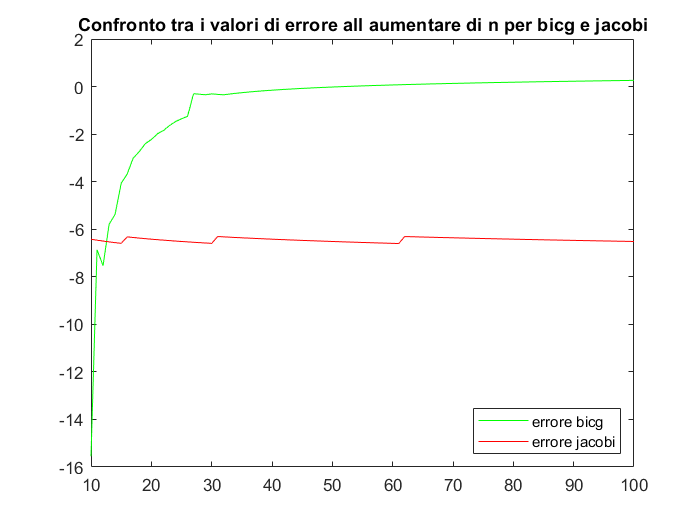

for n=10:100
    A=gallery('poisson',n);
    x=ones(n^2,1);
    b=A*x;
    xc=jacobi(A,b);
    [xc_b,flag]=bicg(A,b);
    err_bicg(n)=norm(xc_b-x)/norm(xc_b);
    err(n)=norm(x-xc)/norm(xc);
end
close all;
x=1:100;
plot(x,log10(err_bicg),'g')
hold on;
plot(x,log10(err),'r')
title('Confronto tra i valori di errore all aumentare di n per bicg e jacobi');
legend('errore bicg','errore jacobi','Location','southeast');

Confronto numero iterazioni con la funzione bicg

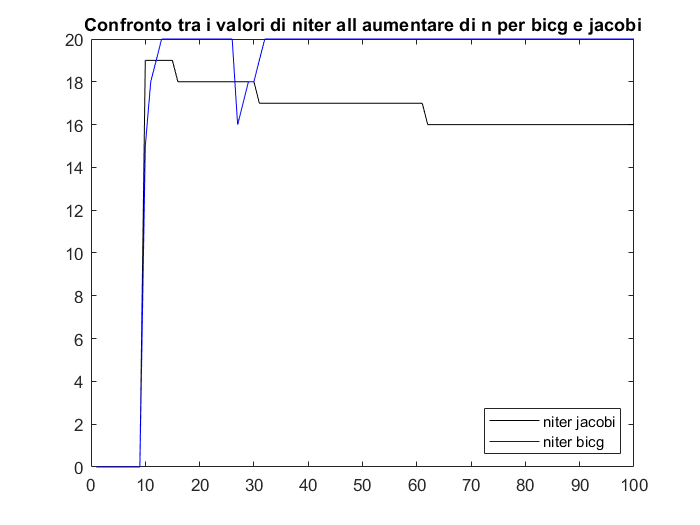

for n=10:100
    A=gallery('poisson',n);
    x=ones(n^2,1);
    b=A*x;
    [xc,niter]=jacobi(A,b);
    [xc_b,flag,resrel,niter2]=bicg(A,b);
    itr1(n)=niter;
    itr2(n)=niter2;
end
close all;
x=1:100;
plot(x,itr1,'k')
hold on;
plot(x,itr2,'b')
title('Confronto tra i valori di niter all aumentare di n per bicg e jacobi');
legend('niter jacobi','niter bicg','Location','southeast');

Calcolo tempo di esecuzione per matrici di varie dimensioni

A=gallery('poisson',20);
x=ones(20^2,1);
b=A*x;
j=@()jacobi(A,b);
tempj=timeit(j)

tempj =    0.007018701150000


A=gallery('poisson',50);
x=ones(50^2,1);
b=A*x;
j=@()jacobi(A,b);
tempj=timeit(j)

tempj = 0.1699

A=gallery('poisson',100);
x=ones(100^2,1);
b=A*x;
j=@()jacobi(A,b);
tempj=timeit(j)

tempj = 1.8955